# **PV**

## GLOBULOS BLANCOS

### a) Anotaciones

close all; clc; clearvars;
% Cargar carpeta del 1º paciente
imageFolder='C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_PvTk\PvTk1'; 

% Cargar imagenes del 1º paciente
imageFiles=dir(fullfile(imageFolder, '*.jpg'));

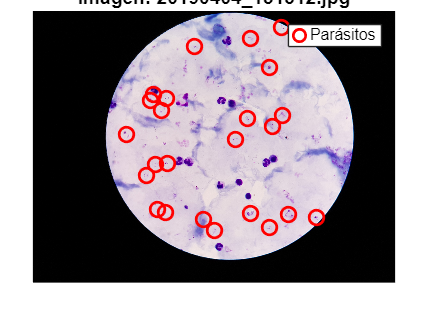

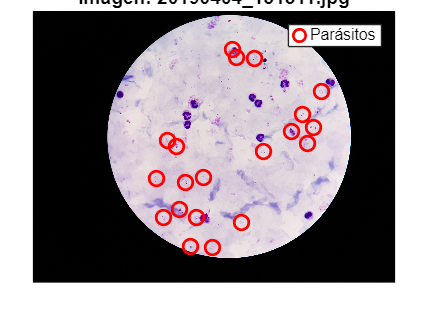

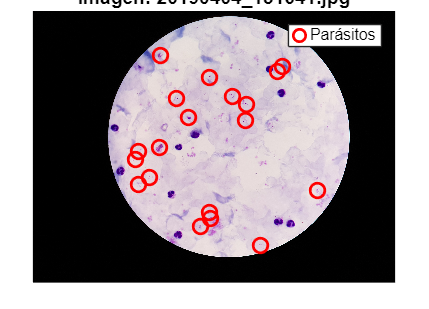

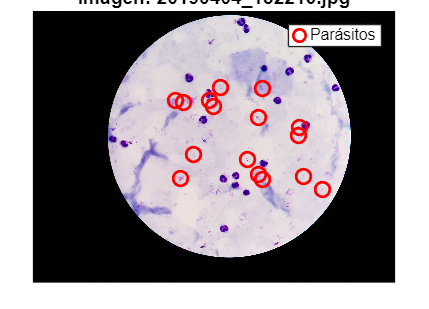

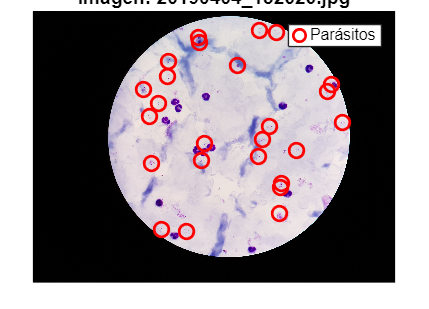

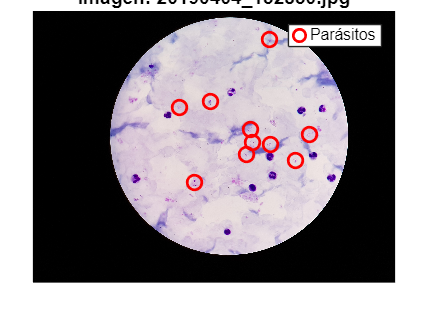

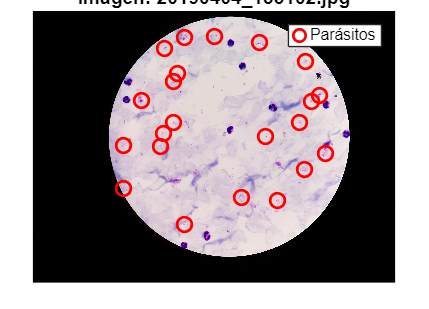

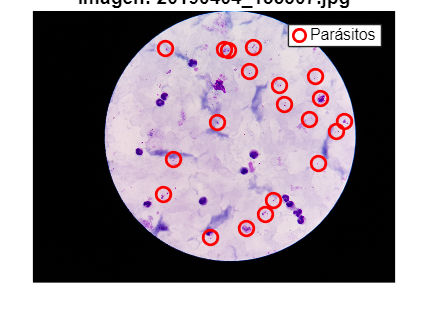

for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    figure;
    imshow(I); hold on;

    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
    
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parásitos');
    hold off;
end

## PARASITOS

### b) 1º Modelo K-means

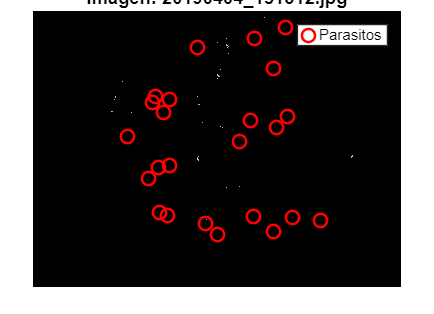

numero_de_parasitos = 24

candidatos_a_parasitos = 63

parasitos_detectados = 2

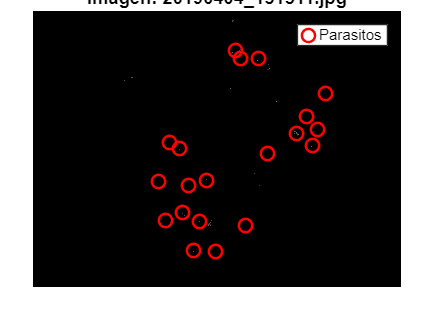

numero_de_parasitos = 20

candidatos_a_parasitos = 45

parasitos_detectados = 13

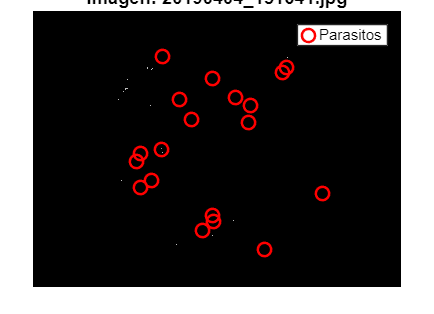

numero_de_parasitos = 19

candidatos_a_parasitos = 78

parasitos_detectados = 6

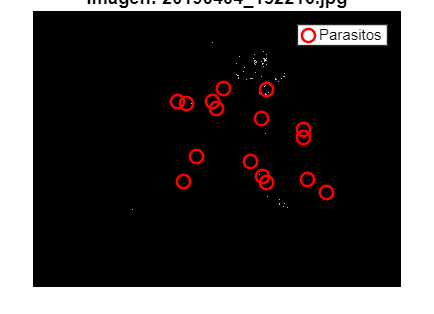

numero_de_parasitos = 16

candidatos_a_parasitos = 120

parasitos_detectados = 2

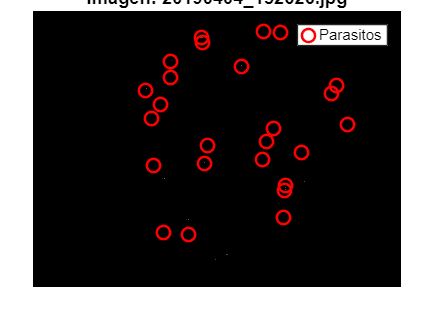

numero_de_parasitos = 25

candidatos_a_parasitos = 18

parasitos_detectados = 10

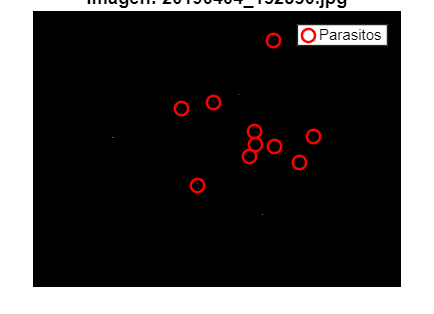

numero_de_parasitos = 10

candidatos_a_parasitos = 10

parasitos_detectados = 4

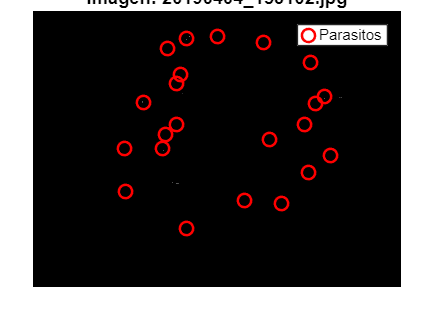

numero_de_parasitos = 22

candidatos_a_parasitos = 17

parasitos_detectados = 9

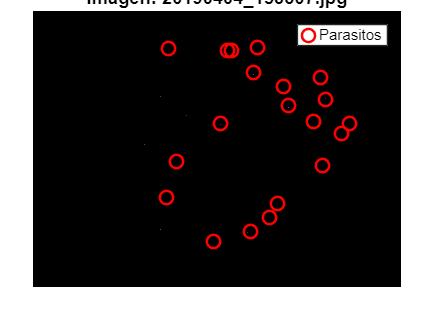

numero_de_parasitos = 20

candidatos_a_parasitos = 28

parasitos_detectados = 13

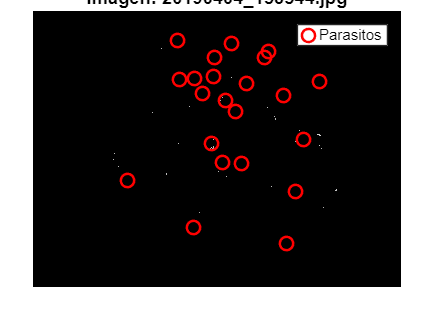

numero_de_parasitos = 22

candidatos_a_parasitos = 80

parasitos_detectados = 5

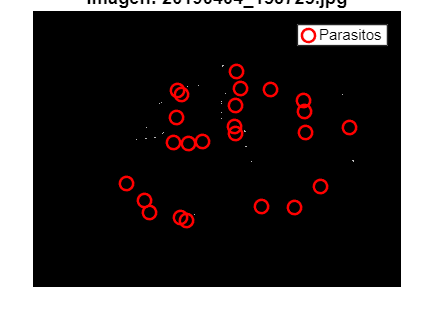

numero_de_parasitos = 24

candidatos_a_parasitos = 49

parasitos_detectados = 2

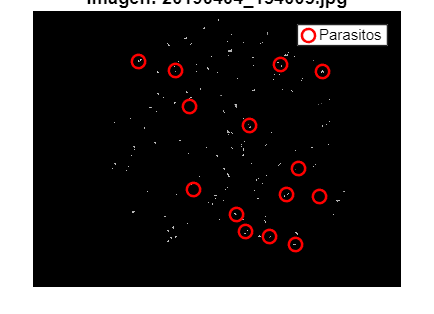

numero_de_parasitos = 14

candidatos_a_parasitos = 261

parasitos_detectados = 12

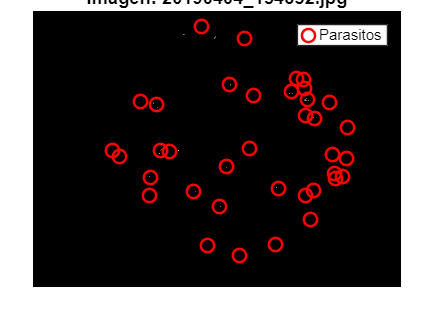

numero_de_parasitos = 37

candidatos_a_parasitos = 38

parasitos_detectados = 23

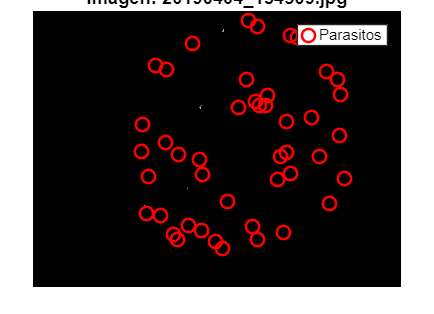

numero_de_parasitos = 45

candidatos_a_parasitos = 14

parasitos_detectados = 0

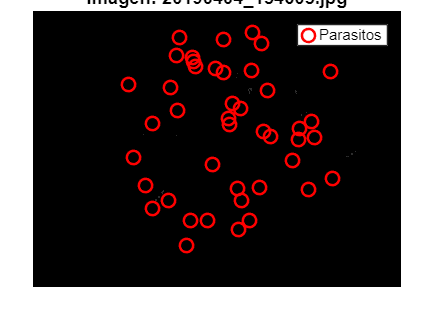

numero_de_parasitos = 43

candidatos_a_parasitos = 26

parasitos_detectados = 1

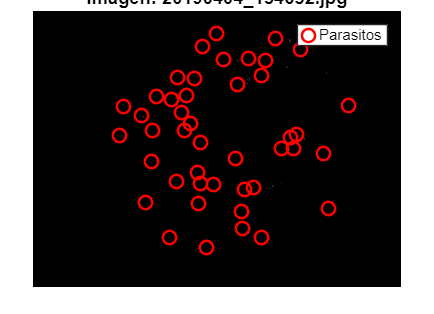

numero_de_parasitos = 44

candidatos_a_parasitos = 25

parasitos_detectados = 1

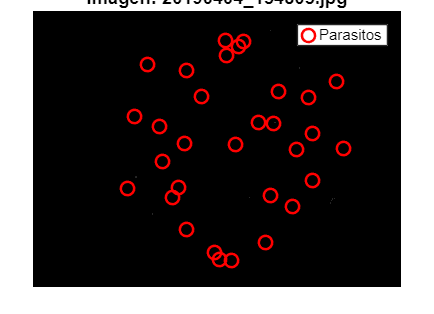

numero_de_parasitos = 31

candidatos_a_parasitos = 19

parasitos_detectados = 1

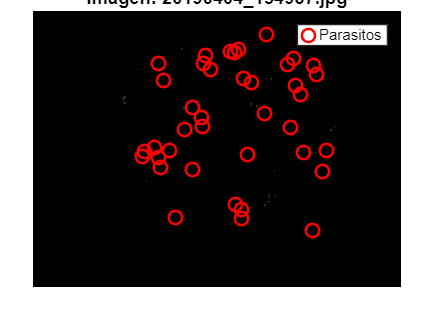

numero_de_parasitos = 39

candidatos_a_parasitos = 33

parasitos_detectados = 3

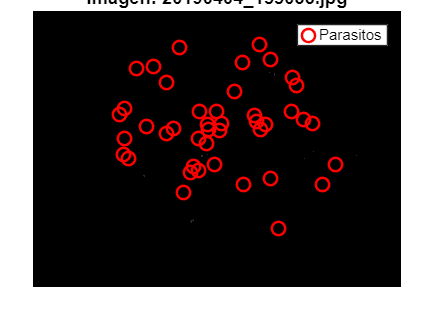

numero_de_parasitos = 43

candidatos_a_parasitos = 15

parasitos_detectados = 0

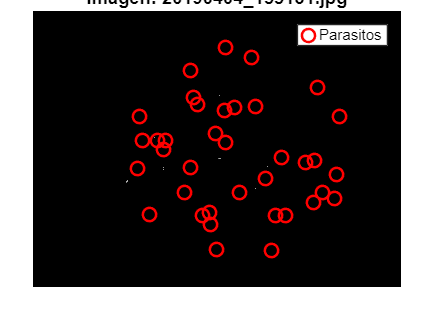

numero_de_parasitos = 37

candidatos_a_parasitos = 23

parasitos_detectados = 1

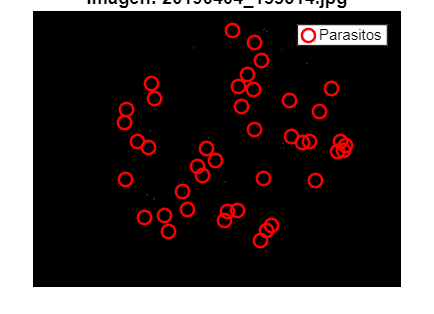

numero_de_parasitos = 42

candidatos_a_parasitos = 22

parasitos_detectados = 0

total_parasitos_reales = 0;
total_candidatos = 0;
total_parasitos_detectados = 0;
for i = 1:length(imageFiles)
    % Nombre completo del archivo
    filename=fullfile(imageFolder, imageFiles(i).name);

    % Cargar la imagen
    I=imread(filename);
    
    % Binario y escala de grises
    I_gray=im2double(rgb2gray(I));
    
    % Filtro
    I_sinruido=medfilt2(I_gray, [3 3]);

    % === K-means para segmentar ===
    I_reshape = reshape(I_sinruido, [], 1);
    [cluster_idx, cluster_centers] = kmeans(double(I_reshape), 3);
    segmented_image = reshape(cluster_idx, size(I_sinruido));
    dark_points_mask = segmented_image == min(segmented_image(:));  % zonas oscuras
    
    % === Glóbulos blancos sin ruido ===
    WBC_mask = bwareaopen(dark_points_mask, 500);
    
    parasite_candidate_mask = dark_points_mask & ~WBC_mask;  % quitar glóbulos blancos
    
    se = strel('disk', 2);  % Estructura de dilatación
    dilated_parasites = imdilate(parasite_candidate_mask, se);
    
    % === Preprocesar para detectar parásitos ===
    parasite_candidate_mask = imfill(dilated_parasites, 'holes');
    parasite_candidate_mask = imopen(dilated_parasites, strel('disk',1));
    
    % === Usar como máscara en la imagen original (opcional) ===
    mascara_parasitos = I_gray;
    mascara_parasitos(~dilated_parasites) = 0;  % fondo negro
    
    % % === Detectar círculos (parásitos) ===
    % [centers, radii] = imfindcircles(mascara_parasitos, [1 4], ...
    %     'ObjectPolarity','dark', 'Sensitivity', 0.93, 'EdgeThreshold', 0.1);
    
    % Visualiza la máscara final
    figure;
    imshow(mascara_parasitos);hold on;
    
    % Carpetas de las anotaciones
    ruta_GT = fullfile('C:\Users\ASUS\Documents\3ºMondragon Universidad\6º Semestre\PBL 6\Procesamiento\Dataset\PV\NIH-NLM-ThickBloodSmearsPV\All_annotations\PvTk1', [imageFiles(i).name(1:end-4), '.txt']);
    
    % Datos de cada carpeta
    datos = readtable(ruta_GT, 'Delimiter', ',', 'HeaderLines', 1);

    % ===== PARÁSITOS =====
    solo_parasitos = datos(strcmp(datos.Var2, 'Parasitized'), :);
    x_parasitos = (solo_parasitos.Var6);
    y_parasitos = (solo_parasitos.Var7);
    plot(x_parasitos, y_parasitos, 'ro', 'MarkerSize', 8, 'LineWidth', 1.5); % círculos rojos
   
    title(['Imagen: ', imageFiles(i).name], 'Interpreter', 'none');
    legend('Parasitos');
    hold off;
    % ============Verificar el modelo========
    
    % Extraer el numero de parasitos
    tamano=size(solo_parasitos);
    numero_de_parasitos = tamano(1,1)

    % Candidatos a parasitos
    n=8;
    CC_2 = bwconncomp(mascara_parasitos,n);
    properties_2 = {'Centroid', 'Circularity', 'Area','Eccentricity', 'Solidity'};
    caracteristicas = regionprops(CC_2,properties_2);
    tamano=size(caracteristicas);
    candidatos_a_parasitos=tamano(1,1)

    % Parasitos detectados
    umbral_distancia = 50;
    parasitos_detectados = 0;

    % Lista para guardar cuáles detecciones ya fueron usadas
    detectados_usados = false(length(caracteristicas), 1);

    % Recorrer cada parásito real
    for p = 1:length(x_parasitos)
        centro_real = [x_parasitos(p), y_parasitos(p)];
        for d = 1:length(caracteristicas)
            if detectados_usados(d)
            continue;  % Saltar si esta detección ya fue usada
            end
            centro_detectado = caracteristicas(d).Centroid;
            distancia = norm(centro_real - centro_detectado);
            if distancia < umbral_distancia
                parasitos_detectados = parasitos_detectados + 1;
                detectados_usados(d) = true;
                break;  % Evita contar un parásito detectado más de una vez
            end
        end
    end
    % Mostrar parasitos detectados
    parasitos_detectados

    % Sumas de los parasitos reales, candidatos y detectados 
    total_parasitos_reales = total_parasitos_reales + numero_de_parasitos;
    total_candidatos = total_candidatos + candidatos_a_parasitos;
    total_parasitos_detectados = total_parasitos_detectados + parasitos_detectados;
end

% Ananlizar modelo con estos resultados
total_parasitos_reales

total_parasitos_reales = 577

total_candidatos

total_candidatos = 984

total_parasitos_detectados

total_parasitos_detectados = 108


% Confusion matrix
TP=total_parasitos_detectados;
FP=total_candidatos-total_parasitos_detectados;
FN=total_parasitos_reales-total_parasitos_detectados;

sensitivity=(TP/(TP+FN))*100

sensitivity = 18.7175

precision=(TP/(TP+FP))*100

precision = 10.9756